## Reading Data

fid = fopen("sample.BIN", "rb", 'b');

if (fid ~= 0)
    disp("Open file succeed!");
else 
    disp("Open file failed!");
end

Open file succeed!



ftell(fid)

ans = 0

N_Sample = 8000000;
SAMPLE_POINT = N_Sample;
head = ftell(fid);

if (head ~= 0)
    fseek(fid, 0,'bof');
end
data_origin = fread(fid, N_Sample*4, 'uint8', 'b');

fclose(fid);
data_origin(1:10);


% uint8 -> dec 
% data = dec2bin(s.UserData); 
data = dec2bin(data_origin);

% d1 = data(:, 25:32)
% d2 = data(:, 17:24)
% d3 = data(:, 9:16)
% d4 = data(:, 1:8)

data_sorted = zeros(SAMPLE_POINT*4,8);
for i=1:SAMPLE_POINT*4
    switch mod(i,4)
        case 1
            data_sorted(i,:) = data(floor(i/4)*4+4, :);
        case 2
            data_sorted(i,:) = data(floor(i/4)*4+3, :);
        case 3
            data_sorted(i,:) = data(floor(i/4)*4+2, :);
        otherwise
            data_sorted(i,:) = data(i-3,:);
    end
end
data_sorted = char(data_sorted);
% data_tag = data_sorted(:,1:2);
% 
% if (sum(mod(find(data_tag=='11'), 4)) > 0 )
%     disp("Data Missing!");
%     index = find(data_tag == '11');
%     index_mod = mod(index, 4);
%     fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 5))
%     
% else
%     disp("Data Right!");
% end

data_sign = str2num(data_sorted(:,3));
data_value = data_sorted(:,4:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign;
data_N4 = reshape(data_value, [4, SAMPLE_POINT])';
clear data_orgin data data_value data_sign data_sorted

## AC Low Speed

Vref = 1.8;
N_SUB = 5;
LSB_SUB = 1.8 / 2^N_SUB;

fclock = 50E6 / 1;           % clk_adc = 10kHz;
fprintf("Number of Sample Points: 64 *  16 tiems average;")

Number of Sample Points: 64 *  16 tiems average;

fs = fclock / 25                % sample rate = 200Hz;

fs = 2000000

fin = 1/256*fs                   % fin = 5/64*fs;

fin = 7.8125e+03


Vout_N4 = data_N4 * LSB_SUB

Vout_N4 =     1.2375    0.0563   -0.0563    0.3375
    1.2375    0.0563   -0.5062    0.2812
    1.2375         0   -0.1125    0.0563
    1.2375         0   -0.5625    0.0563
    1.2375   -0.0563   -0.1125    0.0563
    1.2375   -0.0563   -0.5062    0.3375
    1.2375   -0.1125   -0.1125    0.0563
    1.2375   -0.1688    0.1688    0.1688
    1.2375   -0.1688   -0.1688   -0.3937
    1.2375   -0.1688   -0.5625   -0.1125


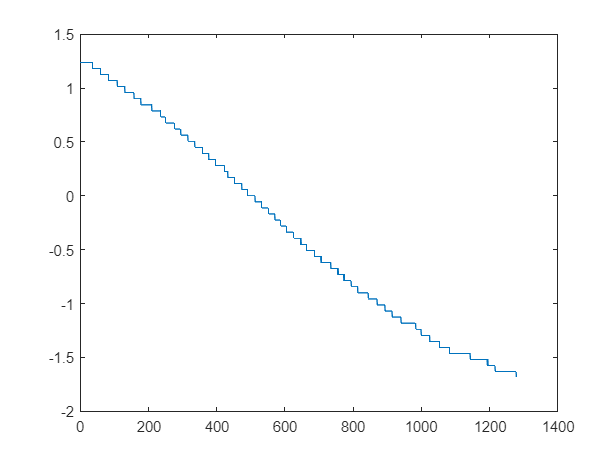

% ~~~~~~~~~~~~~~~ Flash ~~~~~~~~~~~~~~~
figure
plot(Vout_N4(1:1280,1));

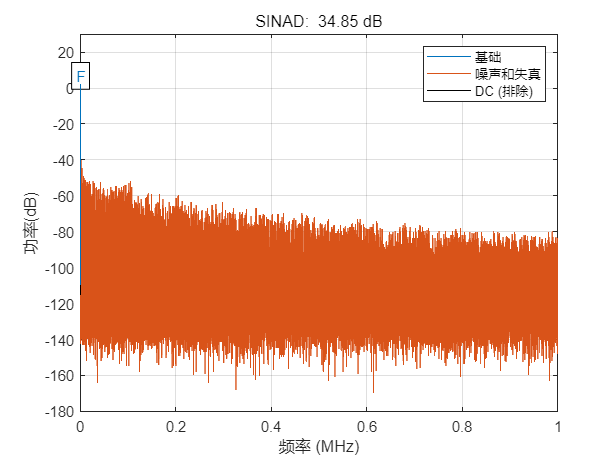

sinad(Vout_N4(:,1), fs);

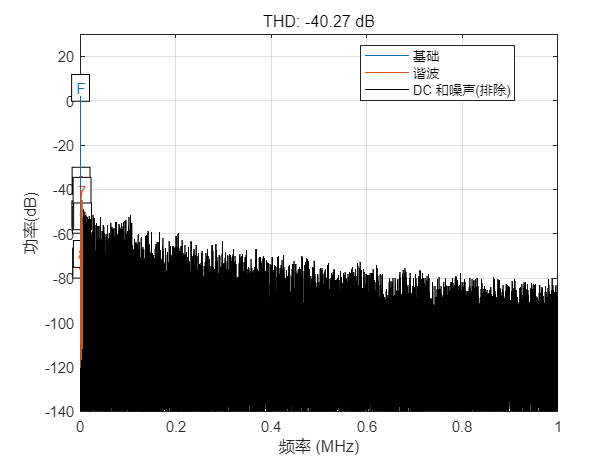

ans = -40.2741

thd(Vout_N4(:,1), fs, 9, "aliased")

% ~~~~~~~~~~~~~~~ without calibration ~~~~~~~~~~~~~~~
Vout_without_calib = zeros(N_Sample, 1);

tic
for i=1:N_Sample
    Vout_without_calib(i) = Calib_Gain(Vout_N4(i,:), 16);
end
toc

历时 7.391544 秒。


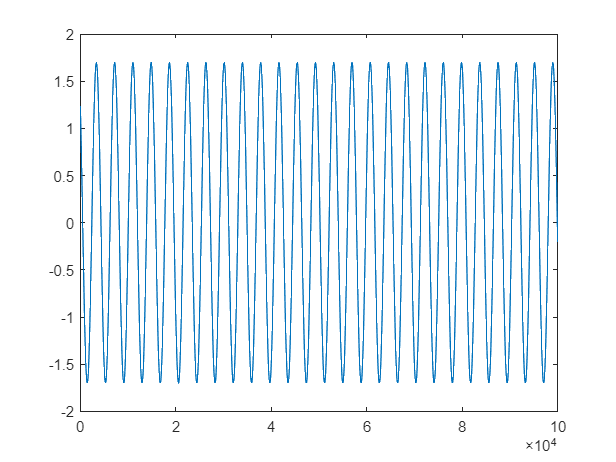


plot(Vout_without_calib(1:100000,1));

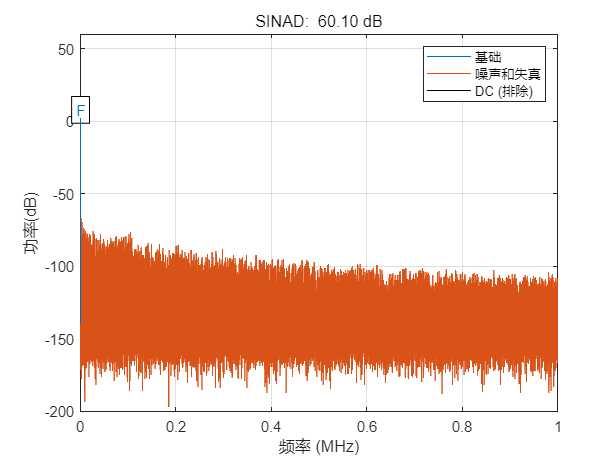

ans = 60.0969


sinad(Vout_without_calib, fs)

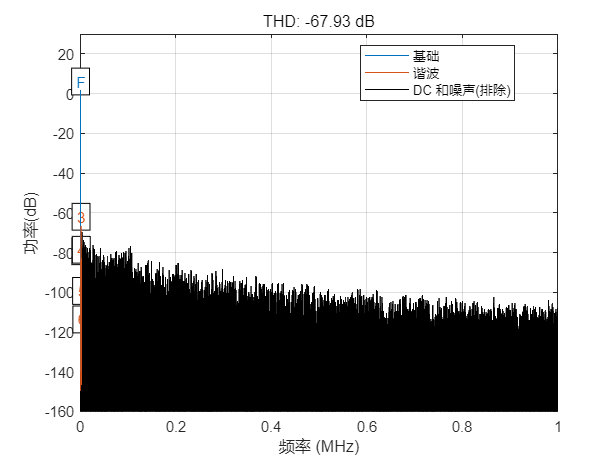

ans = -67.9250

thd(Vout_without_calib, fs, 'aliased')

## Calibration

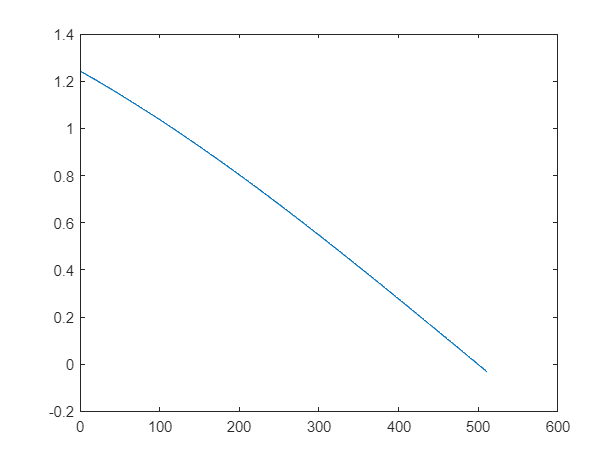

% ~~~~~~~~~~~~~~~ plus calibration ~~~~~~~~~~~~~~~
Vout_plus_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_plus_calib(i) = Calib_Gain(Vout_N4(i,:), abs(GAIN_PLUS));
end
plot(Vout_plus_calib(1:512,1));

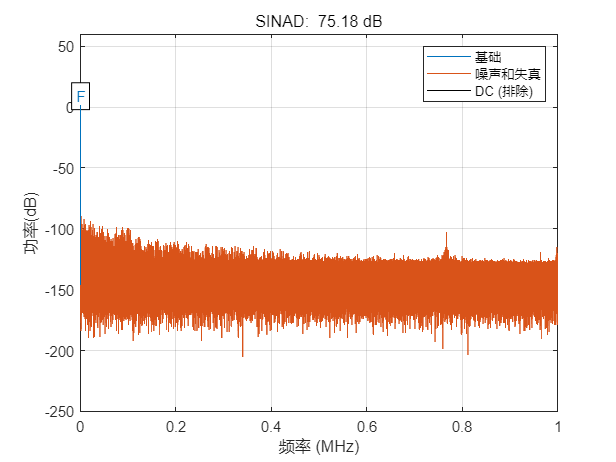

ans = 75.1770

sinad(Vout_plus_calib, fs)

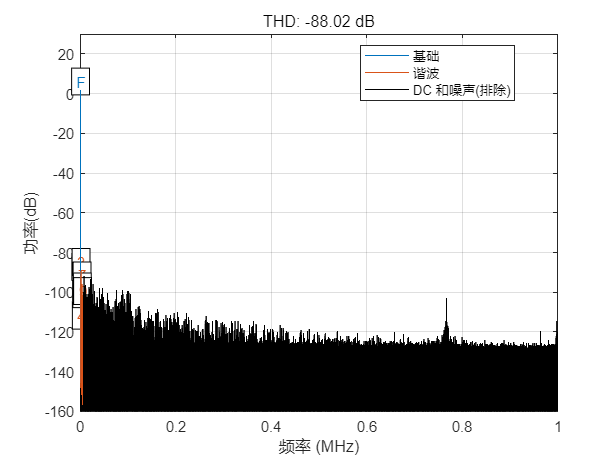

ans = -88.0177

thd(Vout_plus_calib, fs, 9, 'aliased')

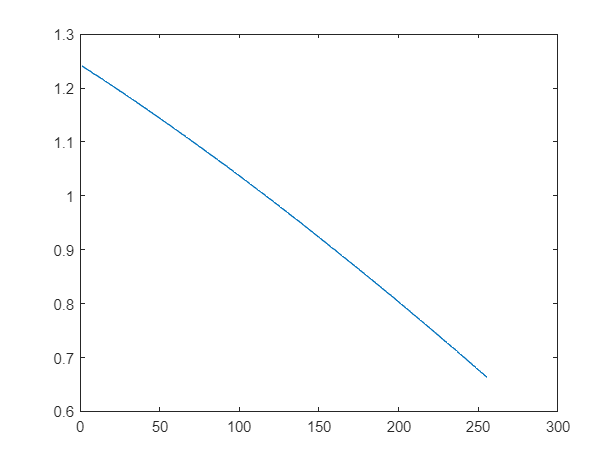



% ~~~~~~~~~~~~~~~ minus calibration ~~~~~~~~~~~~~~~
Vout_minus_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_minus_calib(i) = Calib_Gain(Vout_N4(i,:), GAIN_MIN);
end
plot(Vout_minus_calib(1:256,1));

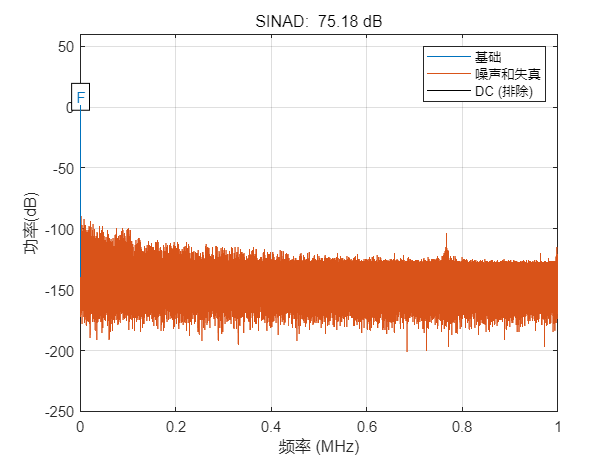

ans = 75.1773

V0 = repmat(Vout_minus_calib, [1,1]);
V1 = V0 .* hamming(length(V0));
sinad(V1, fs)

ans = -88.0177

thd(Vout_minus_calib, fs, 9, 'aliased')


% ~~~~~~~~~~~~~~~ mean calibration ~~~~~~~~~~~~~~~
Vout_mean_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), mean(abs([GAIN_MIN, GAIN_PLUS])));
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end
plot(Vout_mean_calib(1:256,1));

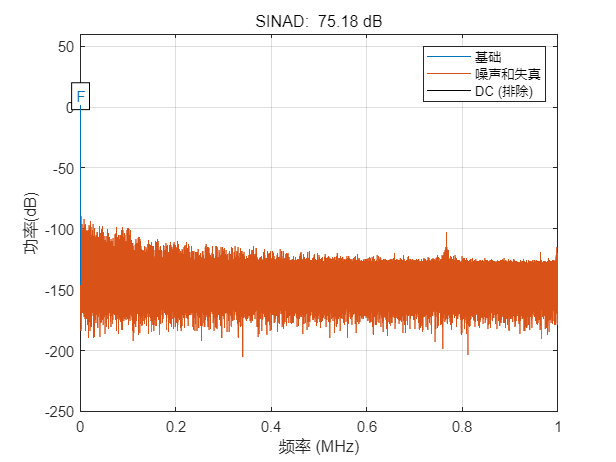

ans = 75.1770

sinad(repmat(Vout_mean_calib,[1 1]), fs)

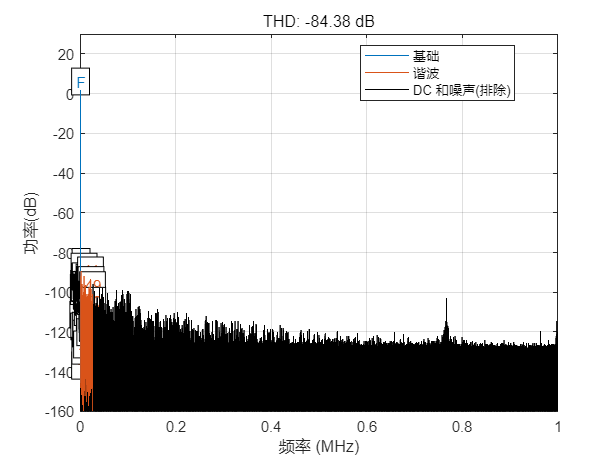

ans = -84.3809

thd(Vout_mean_calib , fs, 50, 'aliased')

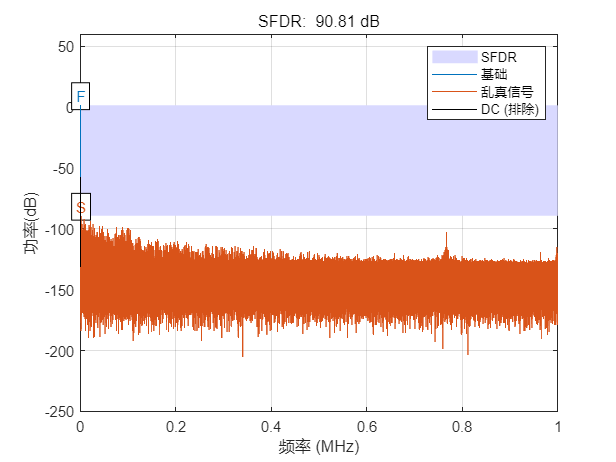

ans = 90.8111

sfdr(Vout_mean_calib, fs)

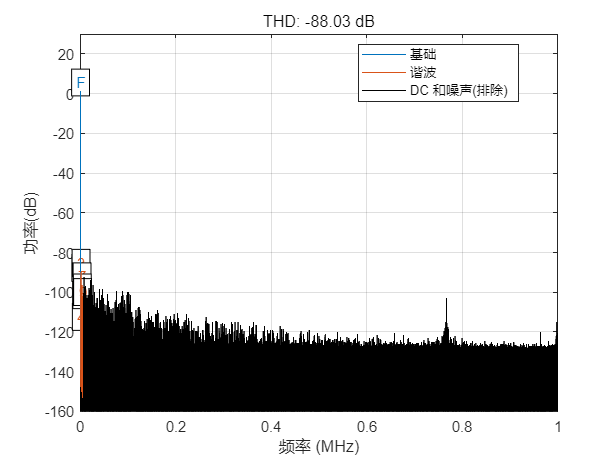

ans = -88.0278

w=hamming(length(Vout_mean_calib));
Vout_windowed = w.*Vout_mean_calib;

thd(Vout_windowed , fs, 9, 'aliased')

ans = 75.1773

sinad(Vout_windowed, fs)

function f_G = f_G(D_array, G)      % f(x)
    f_G = D_array(1) + D_array(2)/G + D_array(3)/G^2 - 2*G;
end

function fd_G = fd_G(D_array, G)    % f'(x)
    fd_G = -D_array(2)/G^2 -2*(D_array(3)/G^3) - 2;
end 


function V_calib = Calib_Gain(V_uncalib, GainA)
    l = length(V_uncalib);
    V_calib = 0;
    for i = 1:l
        V_calib = V_calib + V_uncalib(i) / GainA^(i-1);
    end    

end

function V_calib = Calib_Gain_hybrid(V_uncalib, GainA)
    l = length(V_uncalib);
    V_calib = 0;
    for i = 1:l
        if (V_uncalib(2) > 0)
            V_calib = V_calib + V_uncalib(i) / GainA(2)^(i-1);
        else
            V_calib = V_calib + V_uncalib(i) / GainA(1)^(i-1);
        end
    end
    
end
